eeg1=ar.VarName4;
eeg2=ar.VarName5;
eeg3=ar.VarName6;
eeg4=ar.VarName7;
for i=1:1:length(eeg1)
    if eeg1(i)>3.3
        eeg1(i)=0;
    end
    if eeg1(i)<-3.3 
        eeg1(i)=0;
    end
end
for i=1:1:length(eeg2)
    if eeg2(i)>3.3 
        eeg2(i)=0;
    end
    if eeg2(i)<-3.3 
        eeg2(i)=0;
    end
end
for i=1:1:length(eeg3)
    if eeg3(i)>3.3
        eeg3(i)=0;
    end
    if eeg3(i)<-3.3 
        eeg3(i)=0;
    end
end
for i=1:1:length(eeg4)
    if eeg4(i)>3.3
        eeg4(i)=0;
    end
    if eeg4(i)<-3.3 
        eeg4(i)=0;
    end
end

f=length(eeg1)/120;
t=1/f;
t_D=[0:1:length(eeg2)-1]*t;

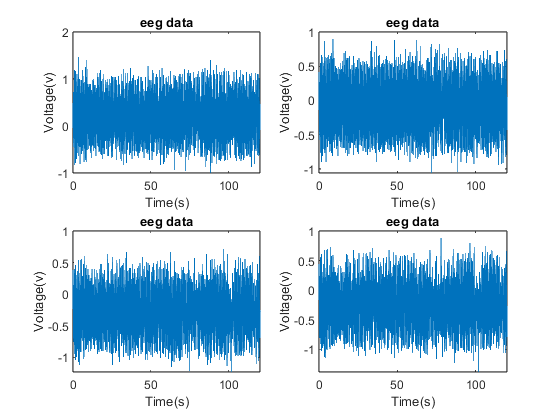

figure;
subplot(2,2,1)
plot(t_D,eeg1)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')

subplot(2,2,2)
plot(t_D,eeg2)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')
subplot(2,2,3)
plot(t_D,eeg3)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')
subplot(2,2,4)
plot(t_D,eeg4)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')

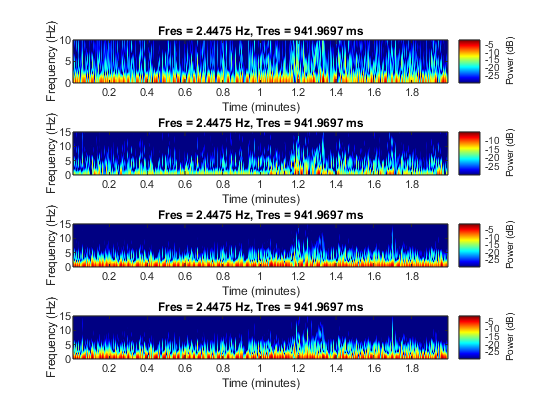

figure;
colormap jet;
subplot(4,1,1)
pspectrum(eeg1,f,"spectrogram","MinThreshold",-30,"FrequencyLimits",[0,10],"Leakage",0.6,"OverlapPercent",90)
subplot(4,1,2)
pspectrum(eeg2,f,"spectrogram","MinThreshold",-30,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)
subplot(4,1,3)
pspectrum(eeg3,f,"spectrogram","MinThreshold",-30,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)
subplot(4,1,4)
pspectrum(eeg4,f,"spectrogram","MinThreshold",-30,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)

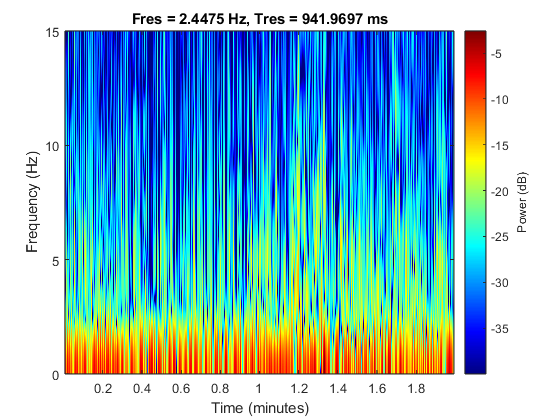

figure;
colormap jet;

pspectrum(eeg1,f,"spectrogram","MinThreshold",-40,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)

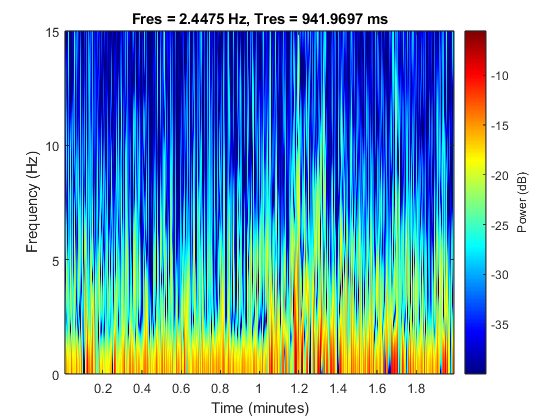

figure;
colormap jet;

pspectrum(eeg2,f,"spectrogram","MinThreshold",-40,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)

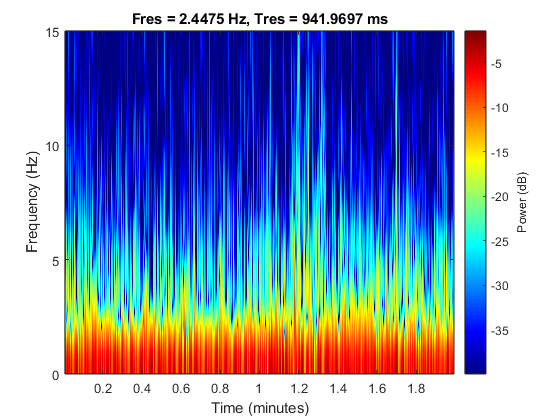

figure;
colormap jet;

pspectrum(eeg3,f,"spectrogram","MinThreshold",-40,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)

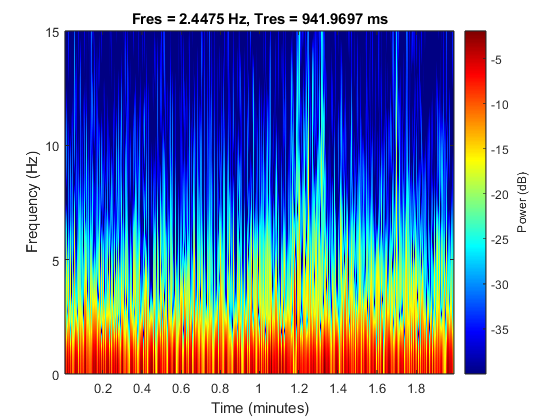

figure;
colormap jet;

pspectrum(eeg4,f,"spectrogram","MinThreshold",-40,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)

output_eeg_trial1115=[eeg1,eeg2,eeg3,eeg4];


writematrix(output_eeg_trial1115,'D:\matlab\ymaps_code\data\output_eeg_23124a3.csv');

